**Authors: **Iván González, Victor Teixidó

# VC - Short Project

## Object recognition in videos

close all
% Read of file groundtruth_rect.txt: frame, bounding box, is_lost
BB = importdata('C:\Users\victo\OneDrive\Escritorio\UNI\vc\shortProject\Boat\groundtruth_rect.txt');
Idir = dir('C:\Users\victo\OneDrive\Escritorio\UNI\vc\shortProject\Boat/img/*.jpg');

## Recognition with Faster-RCNN

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* OBBs

Training on single CPU.
Initializing input data normalization.
|=============================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |      Rate       |
|=============================================================================================================================================|
|       1 |           1 |       00:15:45 |       2.7165 |       59.63% |         0.14 |           86.88% |             1.01 |          0.0010 |
|       1 |           8 |       02:19:11 |       1.8362 |   

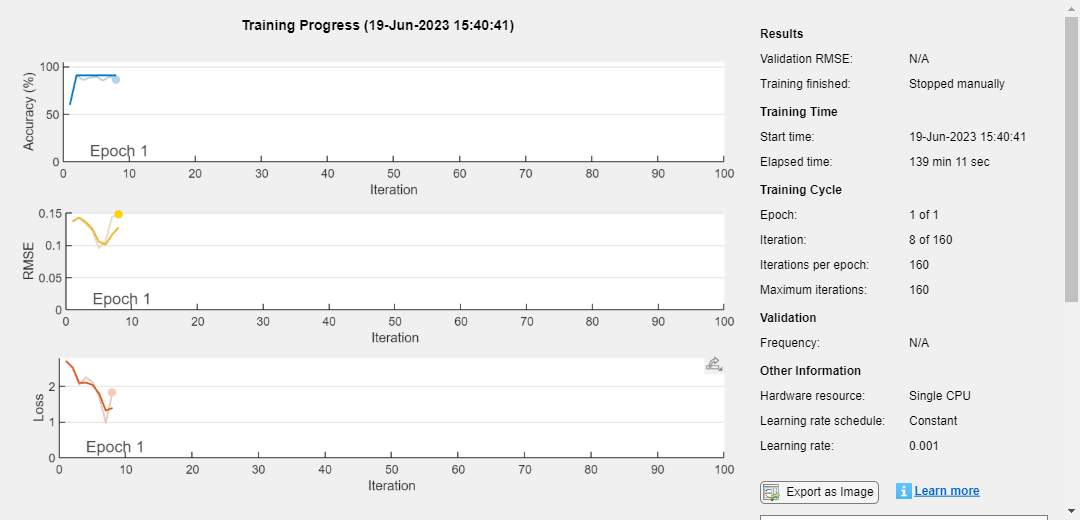

Detector training complete.
*******************************************************************




% Number of frames (all videos have the same #frames)
nf = size(Idir);

% Matrix to store images and bb information
data = getMatrixData(nf, Idir, BB);

[trainData, testData] = splitData(data);

model = trainModel(BB, trainData);


% Check predictions on testData
nFoundCorrectly = 0;
testSize = size(testData);

for i = 1:testSize(1)
    filename = testData{i,1}{1};
    IS = imread(filename);
    [OBB, score, label] = detect(model, IS);

    % Display the object found
    if mod(i, 25) == 0
        displayObjectInScene(IS, OBB, i);
    end

    % Check if is correct
    imgDir = testData{i,1}(1);
    matches = regexp(imgDir, '\d+', 'match');
    idx = str2double(matches{end});
    correctBB = BB(idx,2:5);
    nFoundCorrectly = nFoundCorrectly + isCenterInsideBox(OBB, correctBB);
end

Index exceeds the number of array elements. Index must not exceed 0.

Error in shortProject-Faster_RCNN>isCenterInsideBox (line 107)
    centerOBB = [OBB(1) + OBB(3)/2, OBB(2) + OBB(4)/2];

## Accuracy results

% Print accuracy results
[nf, nFoundCorrectly]
nFoundCorrectly / testSize(1)

## Functions

### Get data information in a matrix

function data = getMatrixData(nf, Idir, BB)
    imageFiles = cell(nf(1), 1);
    OBBs = cell(nf(1), 1);
    
    for i = 1:nf
        filename = horzcat(Idir(i).folder,'/',Idir(i).name);
        imageFiles{i} = filename;
    
        OBB = BB(i, 2:5);
        OBBs{i} = OBB;
    end
    
    data = table(imageFiles, OBBs, 'VariableNames', {'Images', 'OBBs'});
end

### Split data into train and test

function [trainData, testData] = splitData(data)
    trainRatio = 0.8;
    c = cvpartition(size(data, 1), 'HoldOut', 1 - trainRatio);
    trainData = data(c.training, :);
    testData = data(c.test, :);
end

### Create and train the model

function model = trainModel(BB, trainData)
    inputSize = [720, 1280, 3];
    numClasses = 1;
    anchorBoxes = BB(1, 4:5);
    network = 'resnet50';
    layers = fasterRCNNLayers(inputSize, numClasses, anchorBoxes, network);
    
    options = trainingOptions('sgdm', 'MaxEpochs',1, 'MiniBatchSize', 3, 'InitialLearnRate',1e-3, 'Verbose',true, 'ValidationFrequency',10, 'ValidationPatience',5, 'Plots', 'training-progress');
    model = trainFasterRCNNObjectDetector(trainData, layers, options);
end

### Display scene with highlighted object

function displayObjectInScene(IS, OBB, i)
    i
    figure; imshow(IS);
    hold on
    rectangle('Position', OBB, 'EdgeColor', 'yellow');
    hold off
end

### Check if OBB correct

function output = isCenterInsideBox(OBB, CBB)
    centerOBB = [OBB(1) + OBB(3)/2, OBB(2) + OBB(4)/2];
    output = centerOBB(1) > CBB(1) && centerOBB(1) < CBB(1)+CBB(3) && centerOBB(2) > CBB(2) && centerOBB(2) < CBB(2)+CBB(4);
end